## **EX 1**


clear varibles;

measured_data = importdata("tabel1.txt")

measured_data =          0         0
         0    0.3609
         0    0.7134
         0    1.0743
    0.0002    1.2506
         0    1.4352
    0.0002    1.6115
         0    1.7962
    0.0002    1.9724
    0.0002    2.3333


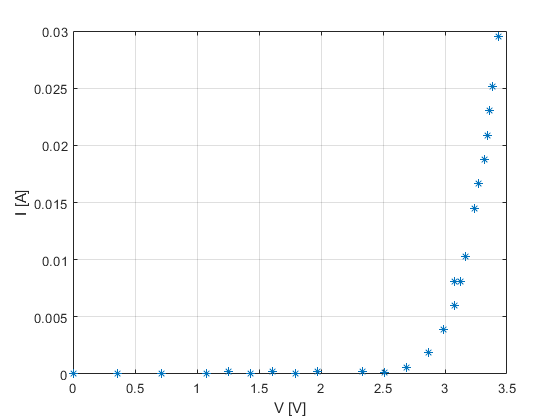


I = measured_data(:,1);
V = measured_data(:,2);

figure, plot(V, I, '*'), grid, xlabel('V [V]'), ylabel('I [A]')


fit_all = fit(V,I,'poly1');

plot(fit_all)
hold on
n = 5; %segmente
idx = [1 6 11 13  18 24];
for i = 1:n
    Ii = I(idx(i) : idx(i+1));
    Vi = V(idx(i) : idx(i+1));
    fit_i = fit(Vi, Ii, 'poly1');
    c = coeffvalues(fit_i)
    aprox1_Ii = c(1) * Vi +c(2);
    plot(Vi, aprox1_Ii, 'b'); hold on;
end

c = 	1.0e+-4 *

    0.5846   -0.1377


c = 	1.0e+-4 *

    0.8602   -0.5048


c =     0.0050   -0.0125


c =     0.0245   -0.0686


c =     0.0609   -0.1823


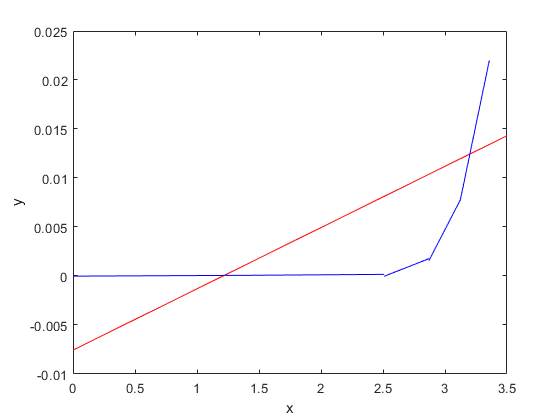

legend off